Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxSta

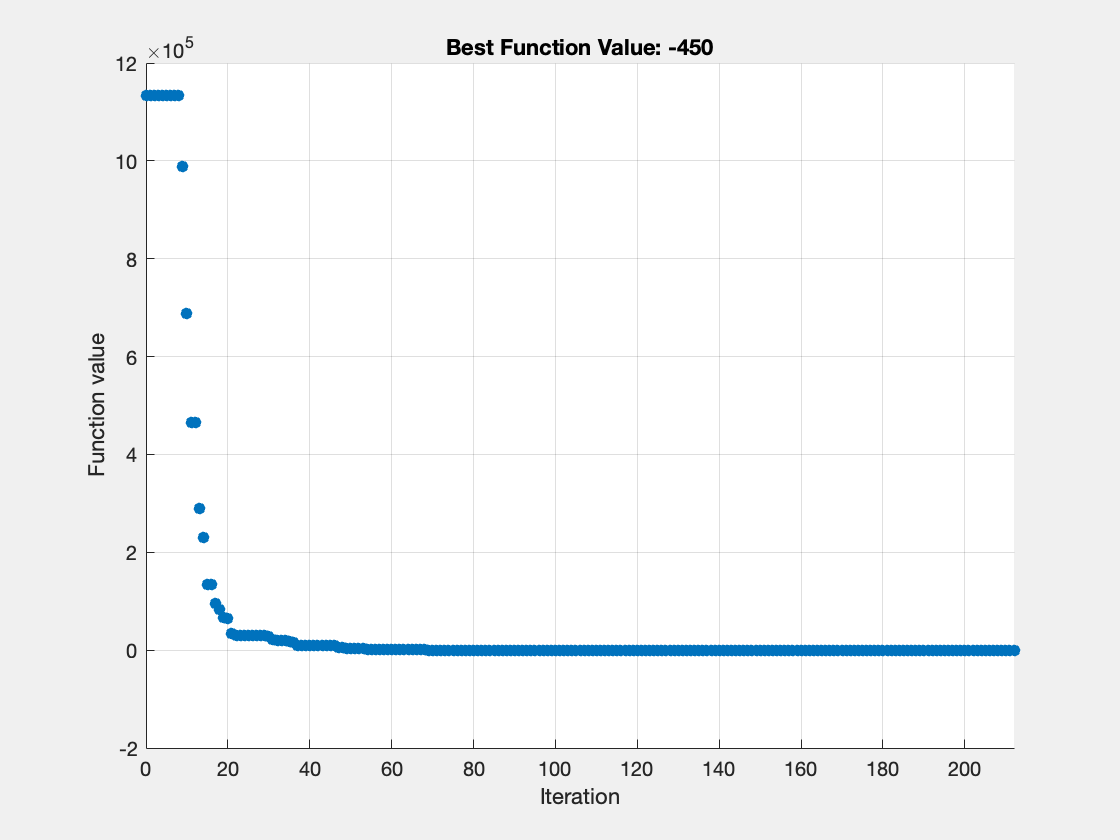

clc, clear, close all
rng default
global initial_flag
%% Particle Swarm Optimization 15 iterations
initial_flag = 0;
options = optimoptions('particleswarm', 'PlotFcn', {@pswplotbestf});
 
% Initialize variables
pso_main_val = zeros(1, 15);
pso_main_exit_flag = zeros(1, 15);
pso_main_op = zeros(1, 15);
 
for i = 1:15
  initial_flag = 0;
   % Particle Swarm Optimization for CEC function 6, D=2
   [pso_x, pso_val, pso_exit_flag, pso_output] = particleswarm(@(x) benchmark_func(x, 2), 10, [], [], options);
  
   % save visualizations to file
   fname = sprintf('filename_pso(%d).fig', i);
  savefig(fname)
 
  
   % Store results in arrays
  pso_main_val(i) = pso_val;
  pso_main_exit_flag(i) = pso_exit_flag;
  
   % Check if 'fval' field exists in the output structure
   if isfield(pso_output, 'fval')
      pso_main_op(i) = min(pso_output.fval);
   else
       % If 'fval' doesn't exist, you may need to adjust accordingly
      pso_main_op(i) = NaN;  % or any appropriate default value
   end
end

 
%% Particle Swarm Optimization 15 iteration measures
pso_val_max = max(pso_main_val);
pso_val_min = min(pso_main_val);
pso_val_mean = mean(pso_main_val);
pso_val_std = std(pso_main_val);
% Print statistics
fprintf('Maximum optimization value: %.4f\n', pso_val_max);

Maximum optimization value: -449.9998


fprintf('Minimum optimization value: %.4f\n', pso_val_min);

Minimum optimization value: -450.0000


fprintf('Mean optimization value: %.4f\n', pso_val_mean);

Mean optimization value: -449.9999


fprintf('Standard deviation of optimization values: %.4f\n', pso_val_std);

Standard deviation of optimization values: 0.0000
